% 0. Define a goal configuration (curvature, length, load)
N_segs = 5;
Q = [0; -3; 0];
p = [0; 80];

overall_g_circ_right_goal = [0.5; 0; 1];
seg_g_circ_right_goal = overall_g_circ_right_goal / N_segs;

% Compute the required internal reaction moments for an arm to reach the
% target
l_0 = overall_g_circ_right_goal(1) * 1.15;
rho_constant = 0.05;
test_straight_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, rho_constant, l_0);
g_circ_right_neutral = test_straight_arm.g_circ_right;

arm_g_circ_right_goal = repmat(overall_g_circ_right_goal, [1, N_segs]);
rxn_needed = test_straight_arm.calc_external_reaction(Q, arm_g_circ_right_goal);
internal_needed = -rxn_needed;

We will now show that such a curvature is unattainable with any sensible arm design: for any arm design defined by its radius and neutral length, the reaction forces and moments it creates does not match the one needed.

N_rhos = 40;
N_ls = 40;
rhos = linspace(0.015, 0.15, N_rhos);
l_0s = linspace(0.55, 0.6, N_ls);

cell_rl = cell(N_rhos, N_ls);
cell_arm_segments = cell(N_rhos, N_ls);
cell_rxns = cell(N_rhos, N_ls);
cell_colors = cell(N_rhos, N_ls);
for i = 1 : N_rhos
    rho_i = rhos(i);
    for j = 1 : N_ls
        l_0_j = l_0s(j);
        % Calculate the internal reaction moment that the muscles would create
        % at that curvature.
        segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0_j);
        segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j));
    
        cell_arm_segments{i, j} = segment_ij;
        cell_rl{i, j} = [rho_i; l_0_j];
        cell_rxns{i, j} = segment_ij.calc_internal_reaction([0; 80], overall_g_circ_right_goal);
        cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
    end
end

mat_rl = [cell_rl{:}];
mat_rxns = [cell_rxns{:}];
mat_hsv = [cell_colors{:}];
mat_rgb = hsv2rgb(mat_hsv');

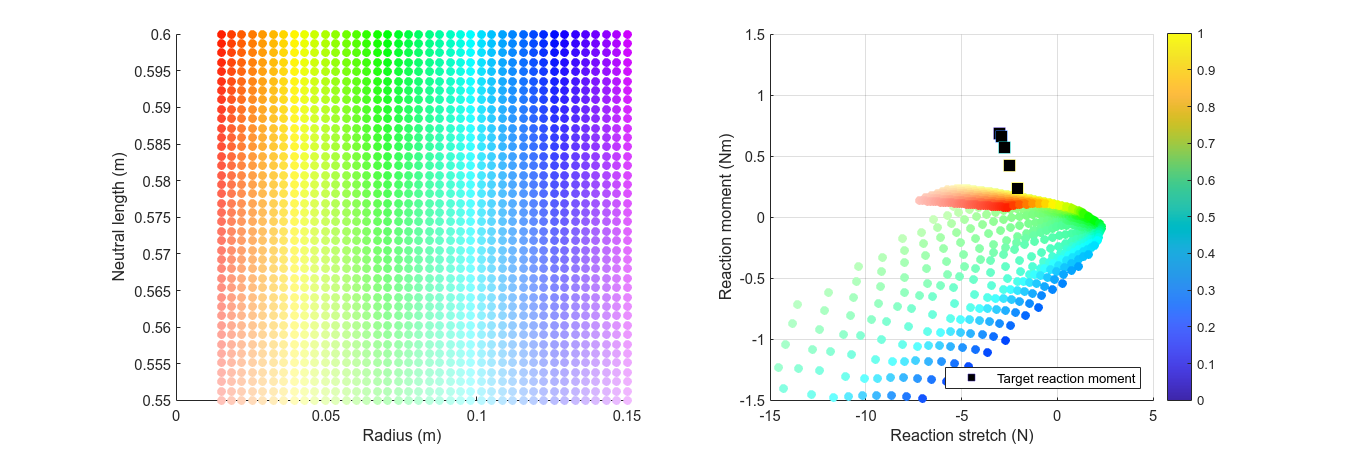

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
scatter(mat_rl(1, :), mat_rl(2, :), [], mat_rgb, "filled");
xlabel("Radius (m)");
ylabel("Neutral length (m)")

subplot(1, 2, 2);
hold on
scatter(mat_rxns(1, :), mat_rxns(3, :), [], mat_rgb, "filled");
scatter(internal_needed(1, :), internal_needed(3, :), 100, linspace(0, 1, N_segs), 'square', "markerfacecolor", 'k')
colorbar
xlim([-15, 5])
ylim([-1.5, 1.5])

grid on
xlabel("Reaction stretch (N)")
ylabel("Reaction moment (Nm)")
legend(["", "Target reaction moment"], "location", "southeast")

While we can see that no design seems capable of reaching the targets, we can still try to reach it by selecting the designs that are closest to reaching each segment's required reaction forces and moments

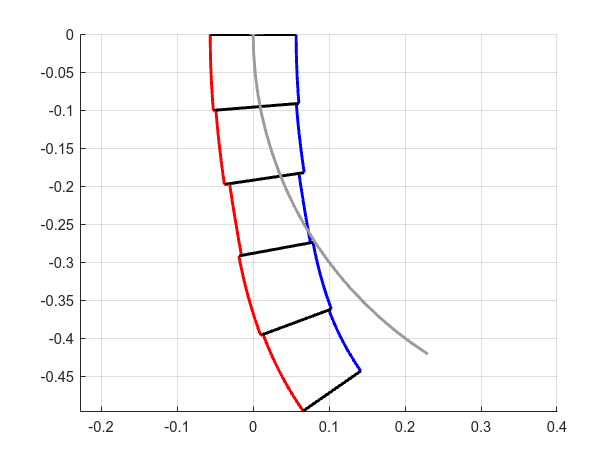

segments = ArmSegment.empty(0, N_segs);
for i = 1 : N_segs
    % For each moment needed, find the arm segment that is capable of
    % producing that. 
    goal_i = internal_needed(:, i);
    [~, i_arm] = min(vecnorm(mat_rxns - goal_i, 1));
    cell_col_arm_segments = cell_arm_segments(:);
    segments(i) = copy(cell_col_arm_segments{i_arm});
end
arm_series = ArmSeries(segments, override_max_s=false);

target_rod = RodSegment(Pose2, overall_g_circ_right_goal(1), segments(1).g_0_o);
target_rod.g_circ_right = overall_g_circ_right_goal;

arm_series.solve_equilibrium_gina(p, Q);
ax = axes(figure());
Plotter2D.plot_arm_series(arm_series, ax);
Plotter2D.plot_rod(target_rod, ax);

As we can see, the arm picked from inverse design is incapable of reaching the target. 

It's impossible for us to design an arm that can reach the target, because we are fundamentally limited by the capabilities of our muscles. To design an arm that *can* reach the goal, we must first answer the question: *what muscles would we need?*

One way to go about this is to first come up with a hypothetical arm design that we would want to reach the goal. If we lock in an arm design, it's a matter of algebra to find the actuator forces required for this arm to reach create the target reaction force/moments

% 1. Define an arm design (segment widths and neutral lengths)
rho_base = 0.07;
rho_tip = 0.08;
l_0 = overall_g_circ_right_goal(1) * 1.15;

arm = ArmSeriesFactory.tapered_2d_muscle_arm(N_segs, rho_base, rho_tip, l_0);
arm.set_mechanics(GinaMuscleMechanics(l_0))
arm.g_circ_right = arm_g_circ_right_goal;
%arm.solve_equilibrium_gina(p, Q);
ax = axes(figure())

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

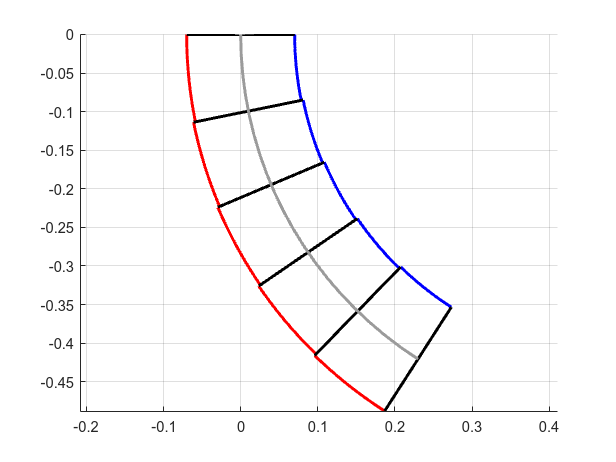

Plotter2D.plot_arm_series(arm, ax)
Plotter2D.plot_rod(target_rod, ax);


% 2. Compute the strains of each muscle
arm_strains = arm.get_strains();

% 3. Compute the forces each muscle needs to pull to create the required
% reaction forces and moments
% NOTE: For a 2-muscle arm, there is a unique solution.
forces_needed = zeros(size(arm_strains));
for i = 1 : size(forces_needed, 2)
    forces_needed(:, i) = pinv(arm.segments(i).mat_A) * internal_needed(:, i);
end

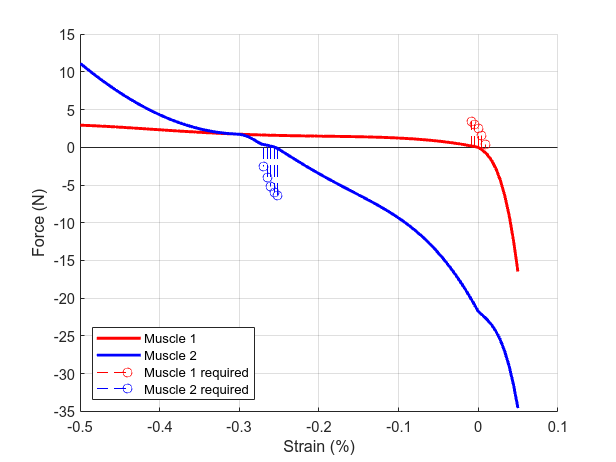

% Plot the required forces as a pretend-muscle-force-curve
figure()
N_strains = 100;
segment = arm.segments(1);
mechanics = segment.mechanics();
N_rods = segment.N_rods;
mat_e_bounds = zeros(N_rods, 2);
for i = 1 : N_rods
    mat_e_bounds(i, :) = mechanics{i}.e_bounds;
end

e_bounds = [min(mat_e_bounds(:, 1)), max(mat_e_bounds(:, 2))];
strains = linspace(e_bounds(1), e_bounds(2), N_strains);

F = zeros(N_rods, N_strains);
for i = 1 : N_rods
    for j = 1 : N_strains
        F(i, j) = mechanics{i}.f_force(strains(j), p(i));
    end
end

hold on
plot(strains, F(1, :), 'r-', 'linewidth', 2)
plot(strains, F(2, :), 'b-', 'linewidth', 2)
stem(arm_strains(1, :), forces_needed(1, :), 'r--')
stem(arm_strains(2, :), forces_needed(2, :), 'b--')
grid on
legend(["Muscle 1", "Muscle 2", "Muscle 1 required", "Muscle 2 required"], 'location', 'southwest')
xlabel("Strain (%)")
ylabel("Force (N)")

Okay. Now that we have requirements (for this given design), let's create muscles with a force curve that meets these requirements, and see if it'll work. 

muscle_1_ft = fittype("a*x", "coefficients", {'a'}, "independent", {'x'});
muscle_1_fit = fit(arm_strains(1, :)', forces_needed(1, :)', muscle_1_ft);

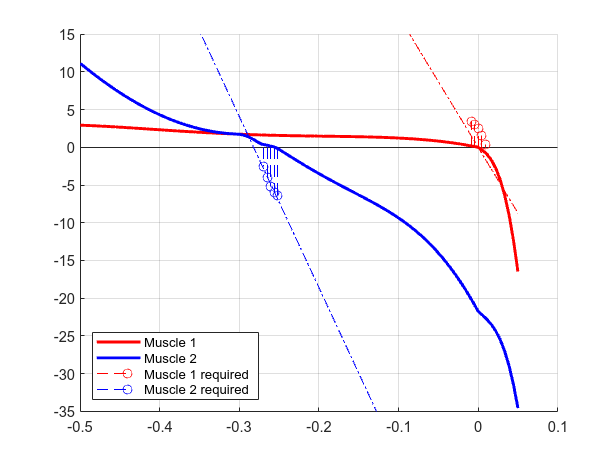

muscle_2_fit = fit(arm_strains(2, :)', forces_needed(2, :)', "poly1");

figure()
hold on
plot(strains, F(1, :), 'r-', 'linewidth', 2)
plot(strains, F(2, :), 'b-', 'linewidth', 2)
stem(arm_strains(1, :), forces_needed(1, :), 'r--')
stem(arm_strains(2, :), forces_needed(2, :), 'b--')
plot(strains, muscle_1_fit(strains), 'r-.')
plot(strains, muscle_2_fit(strains), 'b-.')
ylim([-35,15])
grid on
legend(["Muscle 1", "Muscle 2", "Muscle 1 required", "Muscle 2 required"], 'location', 'southwest')

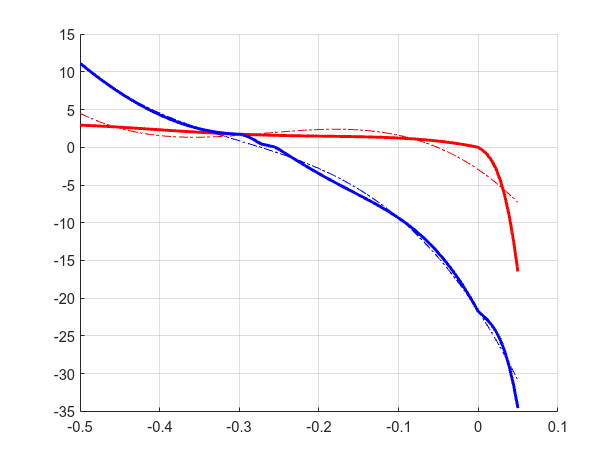

% Fit a cubic fit to the current muscle curves
muscle_1_current_cubic = fit(strains', F(1, :)', "poly3");
muscle_2_current_cubic = fit(strains', F(2, :)', "poly3");
figure()
hold on
plot(strains, F(1, :), 'r-', 'linewidth', 2)
plot(strains, F(2, :), 'b-', 'linewidth', 2)
plot(strains, muscle_1_current_cubic(strains), 'r-.')
plot(strains, muscle_2_current_cubic(strains), 'b-.')
grid on

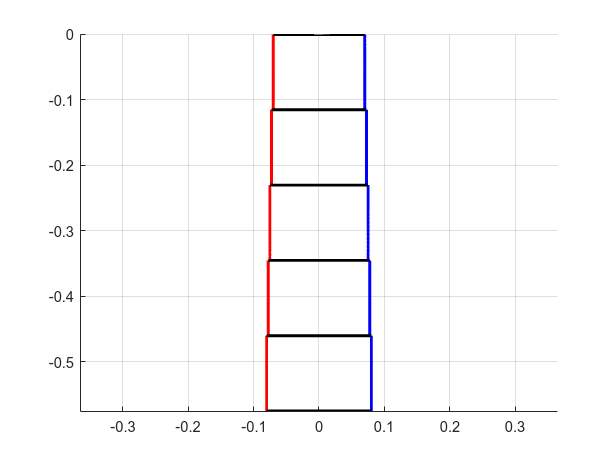

muscle_1_mechanics = RodMechanicsBase(l_0, @(strain, p)(muscle_1_fit(strain)));
muscle_2_mechanics = RodMechanicsBase(l_0, @(strain, p)(muscle_2_fit(strain)));

arm.g_circ_right = g_circ_right_neutral;
arm.set_mechanics(muscle_1_mechanics, 1)
arm.set_mechanics(muscle_2_mechanics, 2)
Plotter2D.plot_arm_series(arm, axes(figure()))

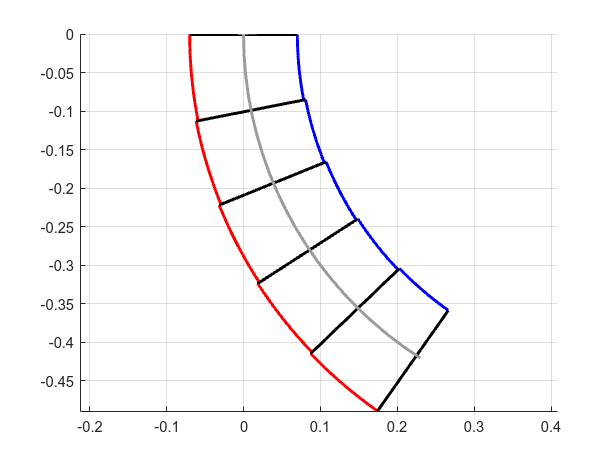

% Solve the equilibrium
arm.solve_equilibrium_gina(p, Q);
ax = axes(figure());
Plotter2D.plot_arm_series(arm, ax)
Plotter2D.plot_rod(target_rod, ax);

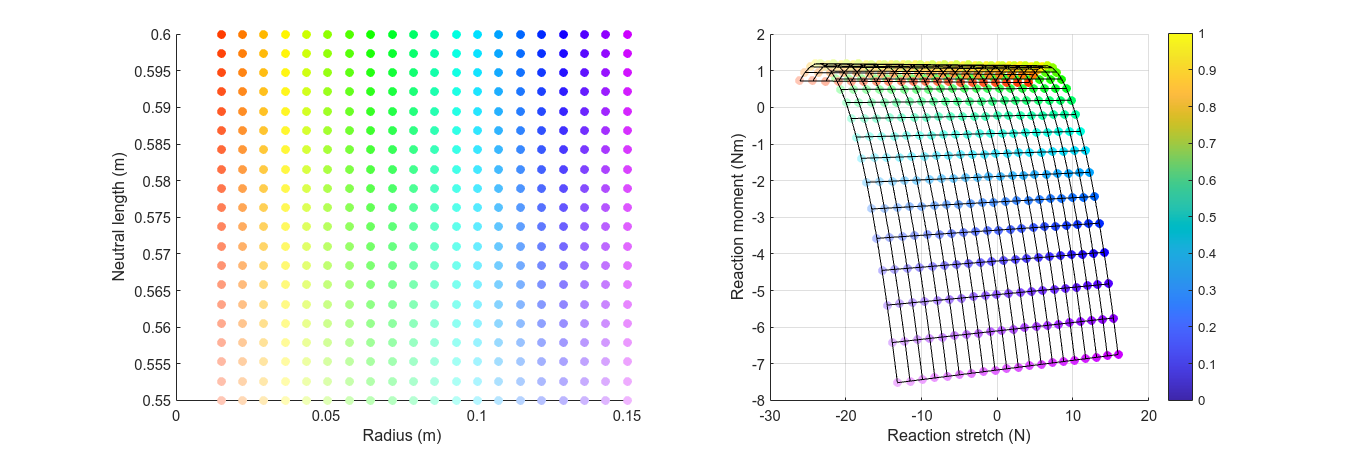

fig = figure("Position", [0, 0, 1500, 500]);
f_moment_image(muscle_1_fit, muscle_2_fit, [0.55, 0.6], [0.015, 0.15], arm_g_circ_right_goal, "fig", fig)

seg_internal_needed = internal_needed(:, 1);

% Sweep across arm widths and lengths - for each width and length , what force does the
% active muscle need to produce?
N_rhos = 10;
N_ls = 10;
rhos = linspace(0.015, 0.15, N_rhos);
l_0s = linspace(0.55, 0.6, N_ls);

cell_rl = cell(N_rhos, N_ls);
cell_arm_segments = cell(N_rhos, N_ls);
cell_strains = cell(N_rhos, N_ls);
cell_forces_req = cell(N_rhos, N_ls);
cell_colors = cell(N_rhos, N_ls);
for i = 1 : N_rhos
    rho_i = rhos(i);
    for j = 1 : N_ls
        l_0_j = l_0s(j);
        % Calculate the internal reaction moment that the muscles would create
        % at that curvature.
        segment_ij = ArmSegmentFactory.make_2d_2muscle(rho_i, l_0_j);
        segment_ij.set_mechanics(GinaMuscleMechanics(l_0_j));
        segment_ij.g_circ_right = diag([1, 1, 1]) * overall_g_circ_right_goal;
    
        cell_arm_segments{i, j} = segment_ij;
        cell_rl{i, j} = [rho_i; l_0_j];
        cell_strains{i, j} = segment_ij.get_strains();
        cell_forces_req{i, j} = pinv(segment_ij.mat_A) * seg_internal_needed;
        cell_colors{i, j} = [i/N_rhos * 0.8; j/N_ls * 0.75 + 0.25; 1];
    end
end

mat_rl = [cell_rl{:}];
mat_strains = [cell_strains{:}];
mat_forces_req = [cell_forces_req{:}];
mat_hsv = [cell_colors{:}];
mat_rgb = hsv2rgb(mat_hsv');

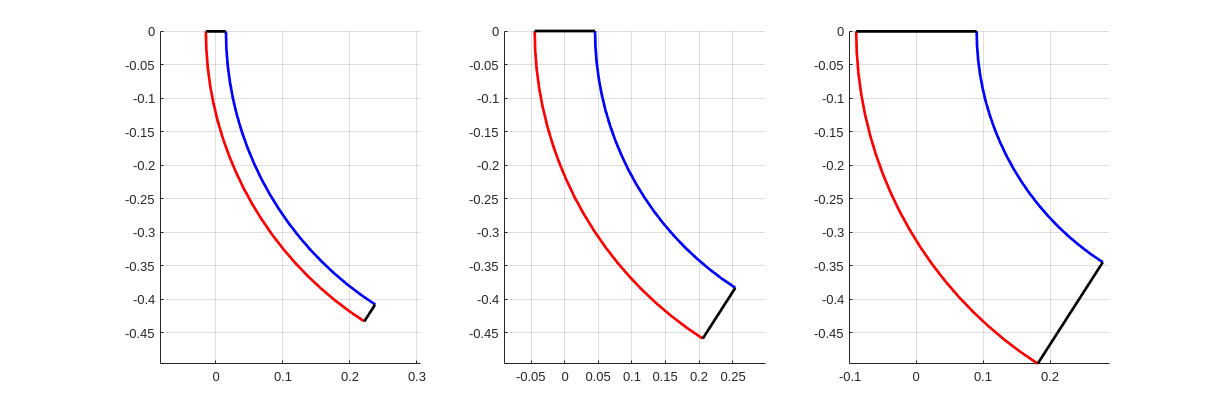

figure('Position', [0, 0, 1500, 500])
ax1 = subplot(1, 3, 1);
Plotter2D.plot_arm_segment(cell_arm_segments{1, 5}, ax1);
grid on

ax2 = subplot(1, 3, 2);
Plotter2D.plot_arm_segment(cell_arm_segments{3, 5}, ax2);
grid on

ax3 = subplot(1, 3, 3);
Plotter2D.plot_arm_segment(cell_arm_segments{6, 5}, ax3);
grid on
linkaxes([ax1, ax2, ax3], 'y')

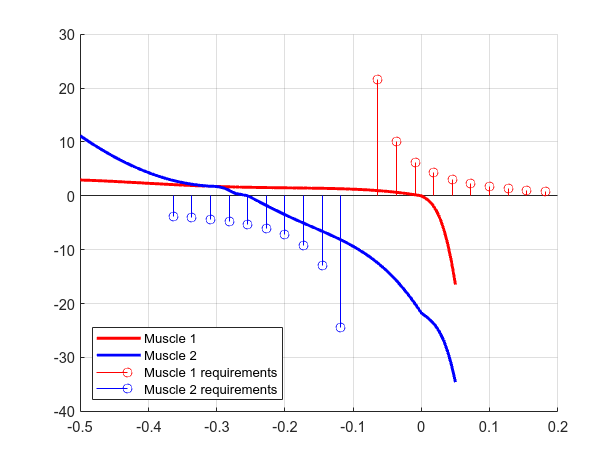

figure()
hold on
plot(strains, F(1, :), 'r-', 'linewidth', 2)
plot(strains, F(2, :), 'b-', 'linewidth', 2)
stem(mat_strains(1, 1:N_rhos), mat_forces_req(1, 1:N_rhos), 'r');
stem(mat_strains(2, 1:N_rhos), mat_forces_req(2, 1:N_rhos), 'b');
grid on
legend(["Muscle 1", "Muscle 2", "Muscle 1 requirements", "Muscle 2 requirements"], 'location', 'southwest')

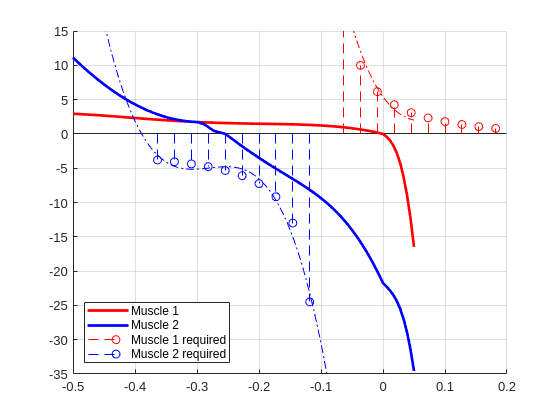

muscle_1_fit = fit(mat_strains(1, 1:N_rhos)', mat_forces_req(1, 1:N_rhos)', "poly3");
muscle_2_fit = fit(mat_strains(2, 1:N_rhos)', mat_forces_req(2, 1:N_rhos)', "poly3");

figure()
hold on
plot(strains, F(1, :), 'r-', 'linewidth', 2)
plot(strains, F(2, :), 'b-', 'linewidth', 2)
stem(mat_strains(1, 1:N_rhos), mat_forces_req(1, 1:N_rhos), 'r--')
stem(mat_strains(2, 1:N_rhos), mat_forces_req(2, 1:N_rhos), 'b--')
plot(strains, muscle_1_fit(strains), 'r-.')
plot(strains, muscle_2_fit(strains), 'b-.')
ylim([-35,15])
grid on
legend(["Muscle 1", "Muscle 2", "Muscle 1 required", "Muscle 2 required"], 'location', 'southwest')

muscle_1_mechanics = RodMechanicsBase(l_0, @(strain, p)(muscle_1_fit(strain)));
muscle_2_mechanics = RodMechanicsBase(l_0, @(strain, p)(muscle_2_fit(strain)));

arm.g_circ_right = g_circ_right_neutral;
arm.set_mechanics(muscle_1_mechanics, 1)
arm.set_mechanics(muscle_2_mechanics, 2)
Plotter2D.plot_arm_series(arm, axes(figure()))

% Solve the equilibrium
arm.solve_equilibrium_gina(p, Q);

fzero residual is nonzero (> 0.01). Printing: 
   -0.0000   -0.0001   -0.0005   -0.0073   -0.4390
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0374    0.0456    0.0515    0.1077    0.3045


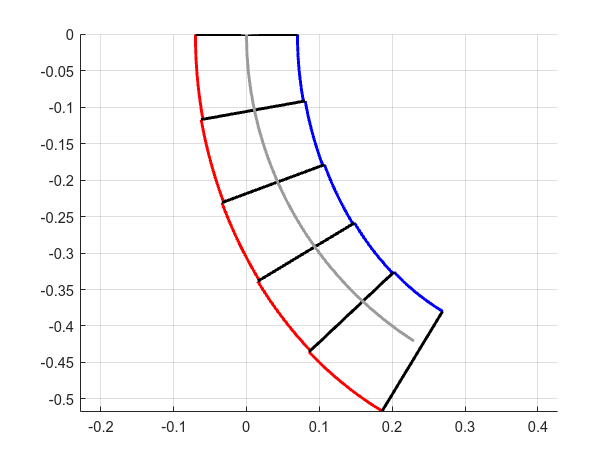

ax = axes(figure());
Plotter2D.plot_arm_series(arm, ax)
Plotter2D.plot_rod(target_rod, ax);

cell_forces = cell(N_segs, N_rhos);
cell_strains = cell(N_segs, N_rhos);

index = zeros(N_segs, N_rhos);
for i = 1 : size(internal_needed, 2)
    for j = 1 : N_rhos
        seg_i = ArmSegmentFactory.make_2d_2muscle(rhos(i), l_0);
        seg_i.set_mechanics(GinaMuscleMechanics(l_0/5))
        seg_i.g_circ_right = diag([0.2, 1, 1]) * overall_g_circ_right_goal;
        cell_strains{i, j} = seg_i.get_strains();
        cell_forces{i, j} = pinv(seg_i.mat_A) * internal_needed(:, i);
        index(i, j) = i;
    end
end

mat_forces = [cell_forces{:}];
mat_strains = [cell_strains{:}];
index = transpose(index);
index = index(:);

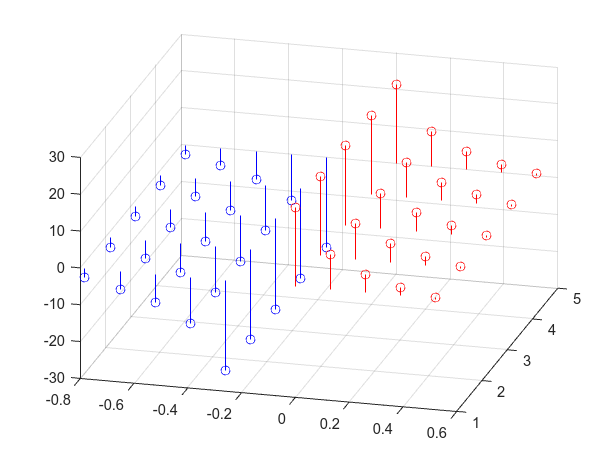

figure()
hold on
stem3(mat_strains(1, :), index, mat_forces(1, :), 'r')
stem3(mat_strains(2, :), index, mat_forces(2, :), 'b')
view(15, 30)
grid on